# Trabajo Práctico 2: Ejercicio 2

clear; clc; close all
s = tf('s');
Gp = 1/((s + 1) * (s + 0.02))

Gp =
 
           1
  -------------------
  s^2 + 1.02 s + 0.02
 
Continuous-time transfer function.
Model Properties


Gp = 1/(s + 0.02)

Gp =
 
     1
  --------
  s + 0.02
 
Continuous-time transfer function.
Model Properties


## Punto A

- Solo controlador proporcional

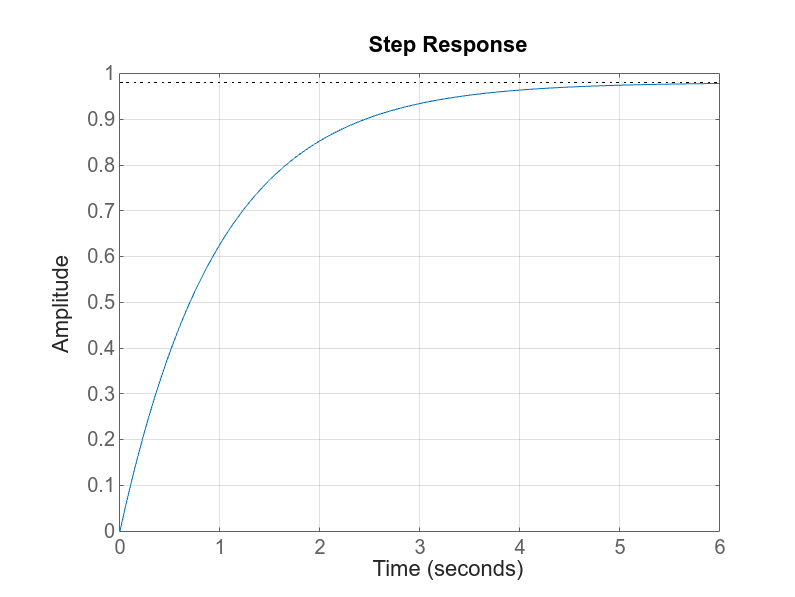

Kp = 1;
Glc = feedback(Kp * Gp, 1);
step(Glc)
grid on

Existe un error finito que disminuye a medida que incrementa Kp, pero nunca será cero.

- Solo contrador derivativo

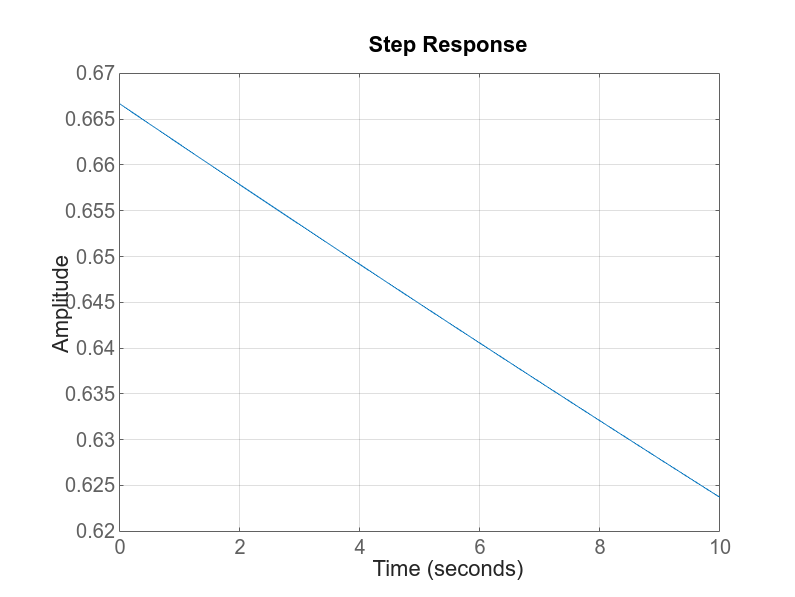

Td = 2;
Gc = Td*s;
Glc = feedback(Gc*Gp, 1);
step(Glc, 10)
grid on

## Punto B

Se propone un controlador PI

Kp = 5;
Ti = 1;
Gc = Kp * (1 + 1/(Ti * s))

Gc =
 
  5 s + 5
  -------
     s
 
Continuous-time transfer function.
Model Properties


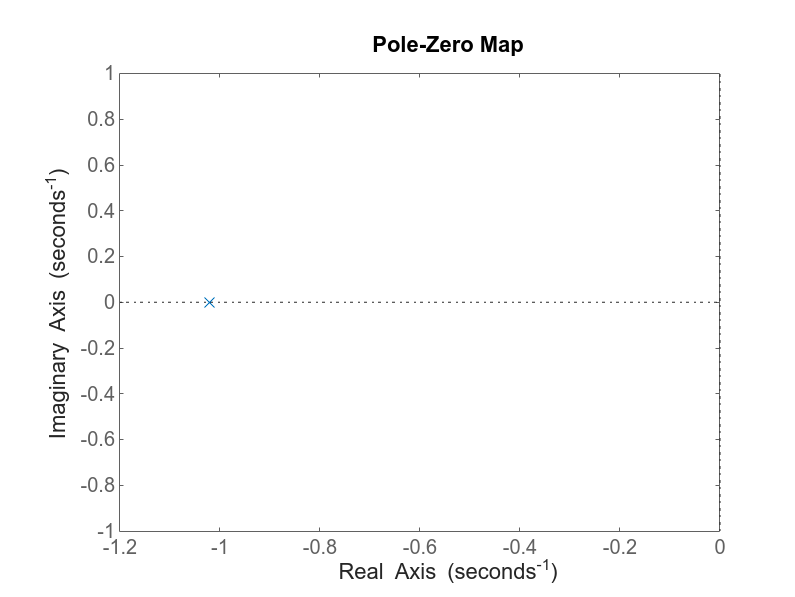

pzplot(feedback(Gp, 1))

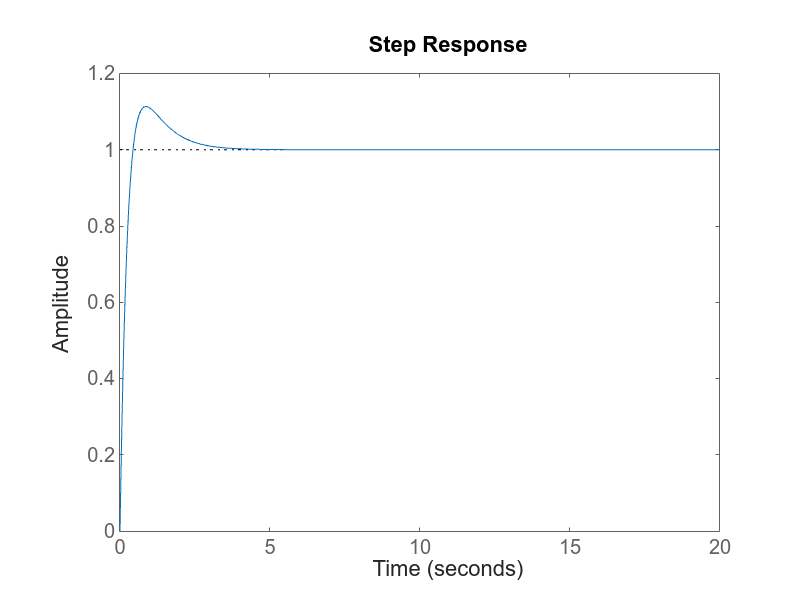

Glc = feedback(Gc * Gp, 1);
step(Glc, 20)

Posee una respuesta subarmortiguada.

stepinfo(Glc)

ans = struct with fields:
         RiseTime: 0.3096
    TransientTime: 2.4660
     SettlingTime: 2.4660
      SettlingMin: 0.9264
      SettlingMax: 1.1133
        Overshoot: 11.3276
       Undershoot: 0
             Peak: 1.1133
         PeakTime: 0.8579


## Punto C

%open_system("tp2ej2c")
sim('tp2ej2c.slx');

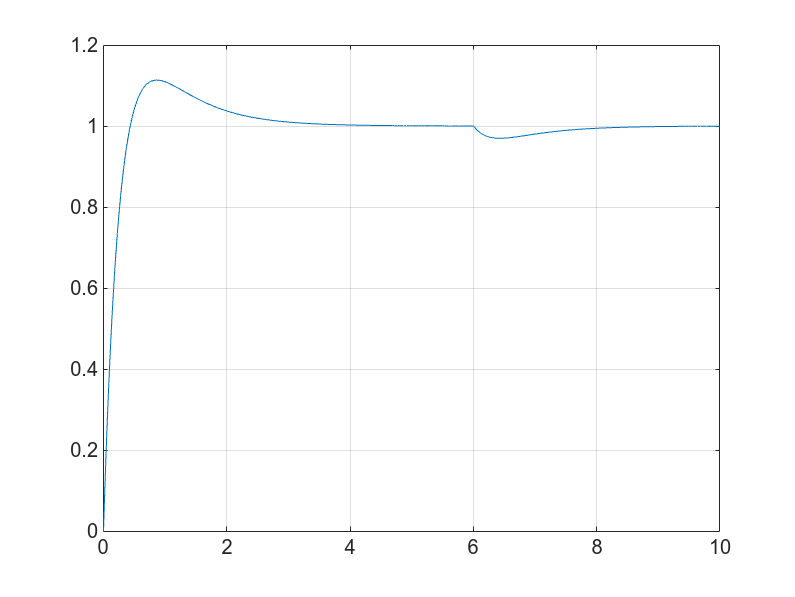

sim_pi = ans.yout.getElement("Y");
tiempo_pi = sim_pi.Values.Time;
resp_pi = sim_pi.Values.Data;
plot(tiempo_pi, resp_pi)
grid on

% plot(out.tout(600000:end) ,out.respuesta(600000:end).*-1.+2)
% grid on
% stepinfo(out.respuesta(600000:end).*-1.+2 ,out.tout(600000:end))

## Punto D

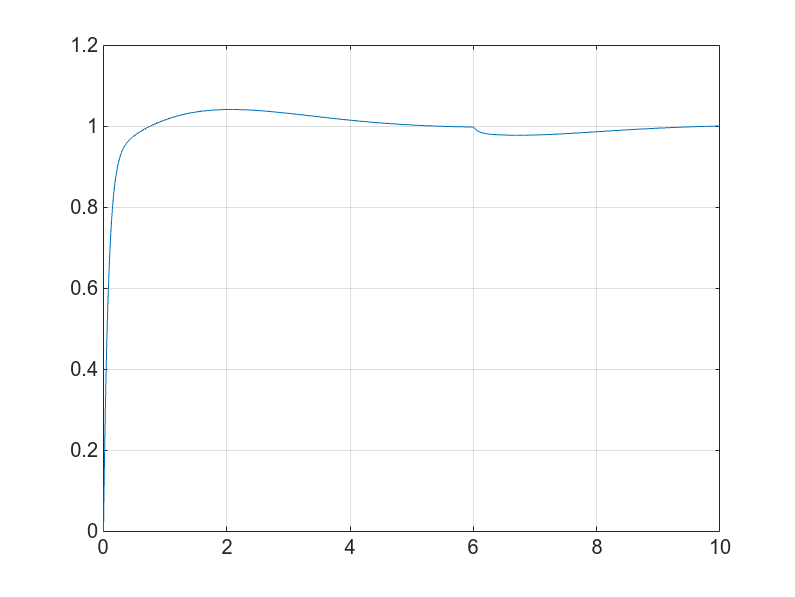

Td = 0.7;
N = 2;
sim('tp2ej2d.slx');
sim_pid = ans.yout.getElement("Y");
tiempo_pid = sim_pid.Values.Time;
resp_pid = sim_pid.Values.Data;
plot(tiempo_pid, resp_pid)
grid on

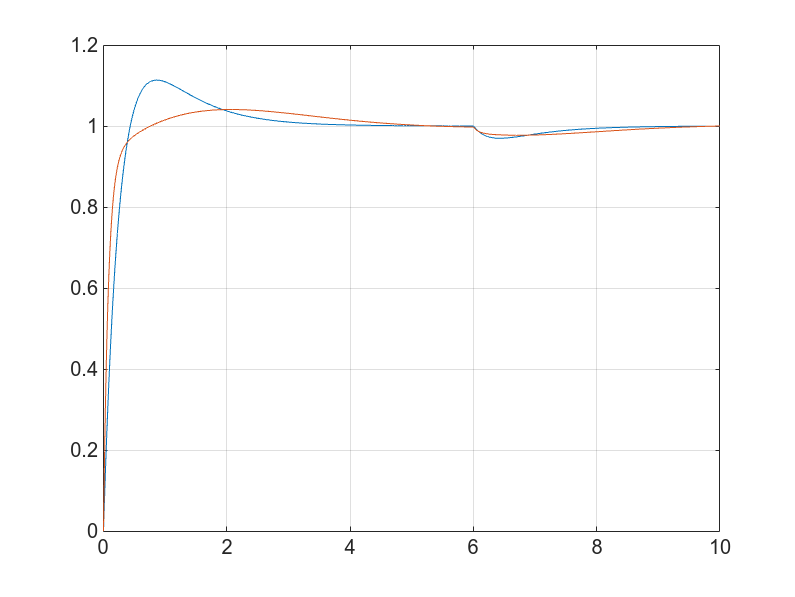

plot(tiempo_pi, resp_pi, tiempo_pid, resp_pid)
grid on

C0 = pidstd(1,1,1);
C = pidtune(feedback(Gp, 1), C0)

C =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 1.46, Ti = 0.541, Td = 5.5e-05
 
Continuous-time PID controller in standard form
Model Properties


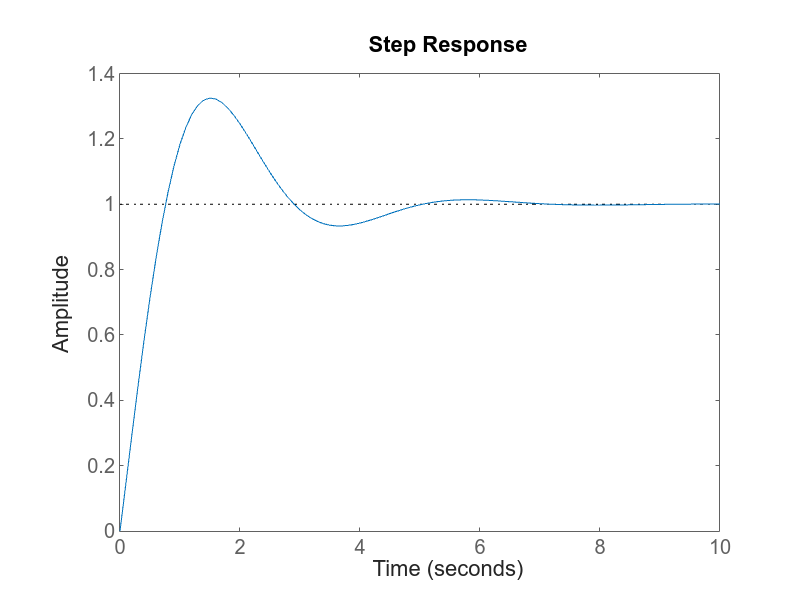

step(feedback(C * Gp, 1), 10)

## Punto E

%Gc = Kp * (1 + 1/(Ti * s) + Td * (N/(1 + N * 1/s)));
Gc = pidstd(Kp, Ti, Td)

Gc =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 5, Ti = 1, Td = 0.7
 
Continuous-time PID controller in standard form
Model Properties


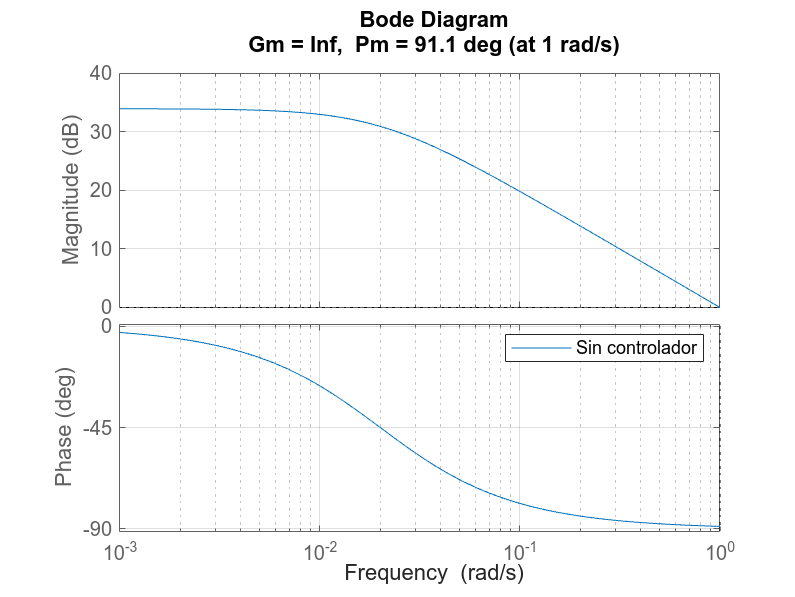

% h = bodeplot(Gp);
% h.showCharacteristic('AllStabilityMargins'); hold on
% g = bodeplot(Gc * Gp);
% g.showCharacteristic('AllStabilityMargins'); hold off
margin(Gp)
grid on
legend('Sin controlador')

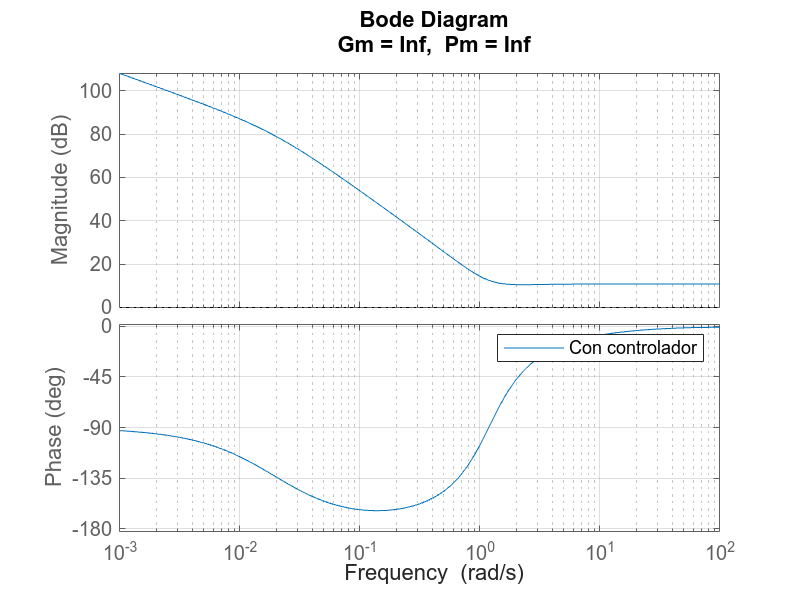

margin(Gc * Gp)
grid on
legend('Con controlador')

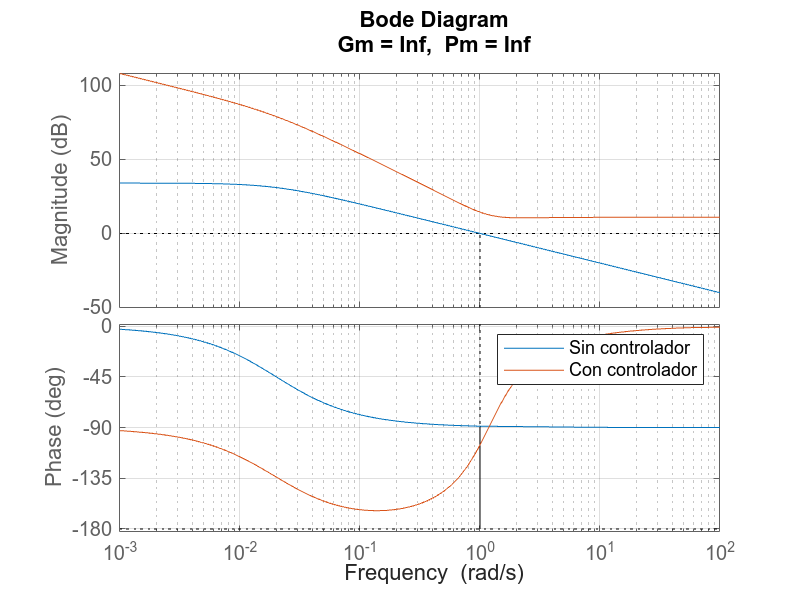

margin(Gp); hold on
margin(Gc * Gp); hold off
grid on
legend('Sin controlador', 'Con controlador')

## Punto F

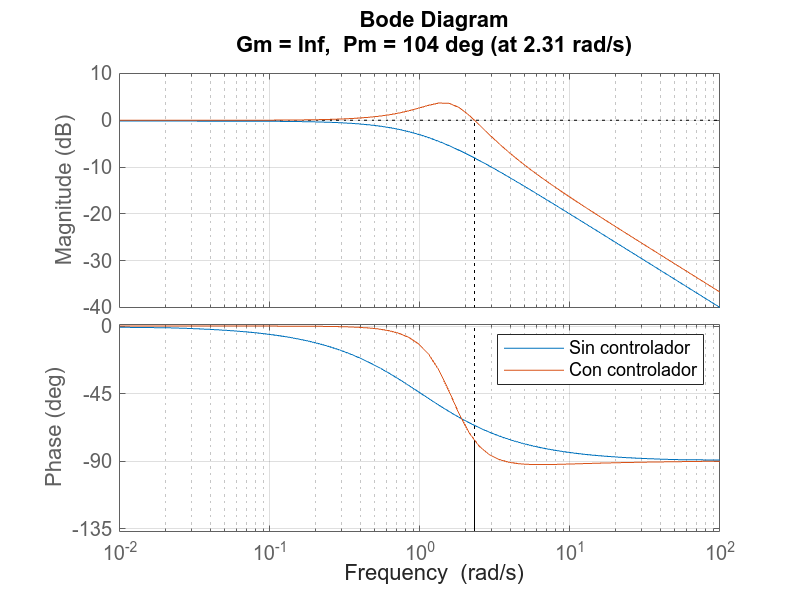

h1 = feedback(Gp, 1);
h2 = feedback(C * Gp, 1);
margin(h1); hold on
margin(h2); hold off
grid on
legend('Sin controlador', 'Con controlador')

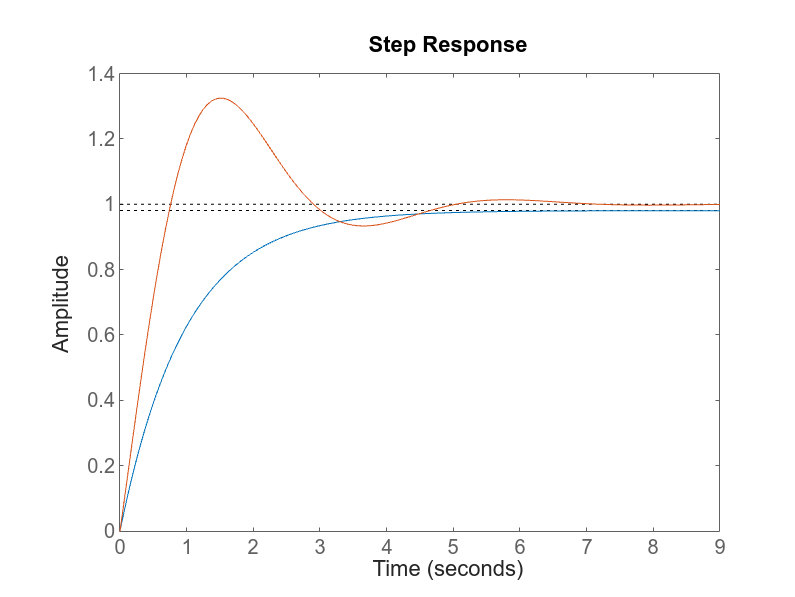

step(h1, h2)

stepinfo(h1)

ans = struct with fields:
         RiseTime: 2.1539
    TransientTime: 3.8354
     SettlingTime: 3.8354
      SettlingMin: 0.8868
      SettlingMax: 0.9797
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9797
         PeakTime: 7.1786


stepinfo(h2)

ans = struct with fields:
         RiseTime: 0.5925
    TransientTime: 4.6407
     SettlingTime: 4.6406
      SettlingMin: 0.9261
      SettlingMax: 1.3247
        Overshoot: 32.4674
       Undershoot: 0
             Peak: 1.3247
         PeakTime: 1.4935
